# Example: MHKiT-MATLAB Quality Control Module 

The following example runs a simple quality control analysis on wave elevation data using the [MHKiT QC module](https://mhkit-code-hub.github.io/MHKiT/source/mhkit-matlab/mhkit.qc.html). The data file used in this example is stored in the [\MHKiT\examples\data](https://github.com/MHKiT-Code-Hub/MHKiT-MATLAB/tree/master/examples/data) directory.

## Import Data

Load the data into a table. The data includes several issues, including timestamps that are out of order, corrupt data with values of -999, data outside expected range, and stagant data. 

data=readtable('../examples/data/qc/wave_elevation_data.csv');
disp(data)

     Time     probe1    probe2    probe3
    ______    ______    ______    ______

        10     24.48     28.27      1.3 
    10.002     34.48     40.27     -8.7 
    10.004     30.48     38.27    -13.7 
    10.006     12.48     24.27    -32.7 
    10.008     13.48     22.27    -21.7 
     10.01      7.48     15.27    -13.7 
    10.012      4.48     13.27    -19.7 
    10.014     -9.52     -0.73    -11.7 
    10.016      8.48     19.27    -16.7 
    10.018     -4.52      8.27    -34.7 
     10.02     16.48     27.27      5.3 
    10.022    -13.52     -0.73    -36.7 
    10.024    -13.52      0.27    -39.7 
    10.026    -15.52     -3.73    -32.7 
    10.028    -22.53    -17.73    -23.7 
     10.03    -22.52    -16.73     16.3 
    10.032    -30.52    -23.73      1.3 
    10.034    -30.52    -16.73     11.3 
    10.036    -36.52    -24.73     13.3 
  

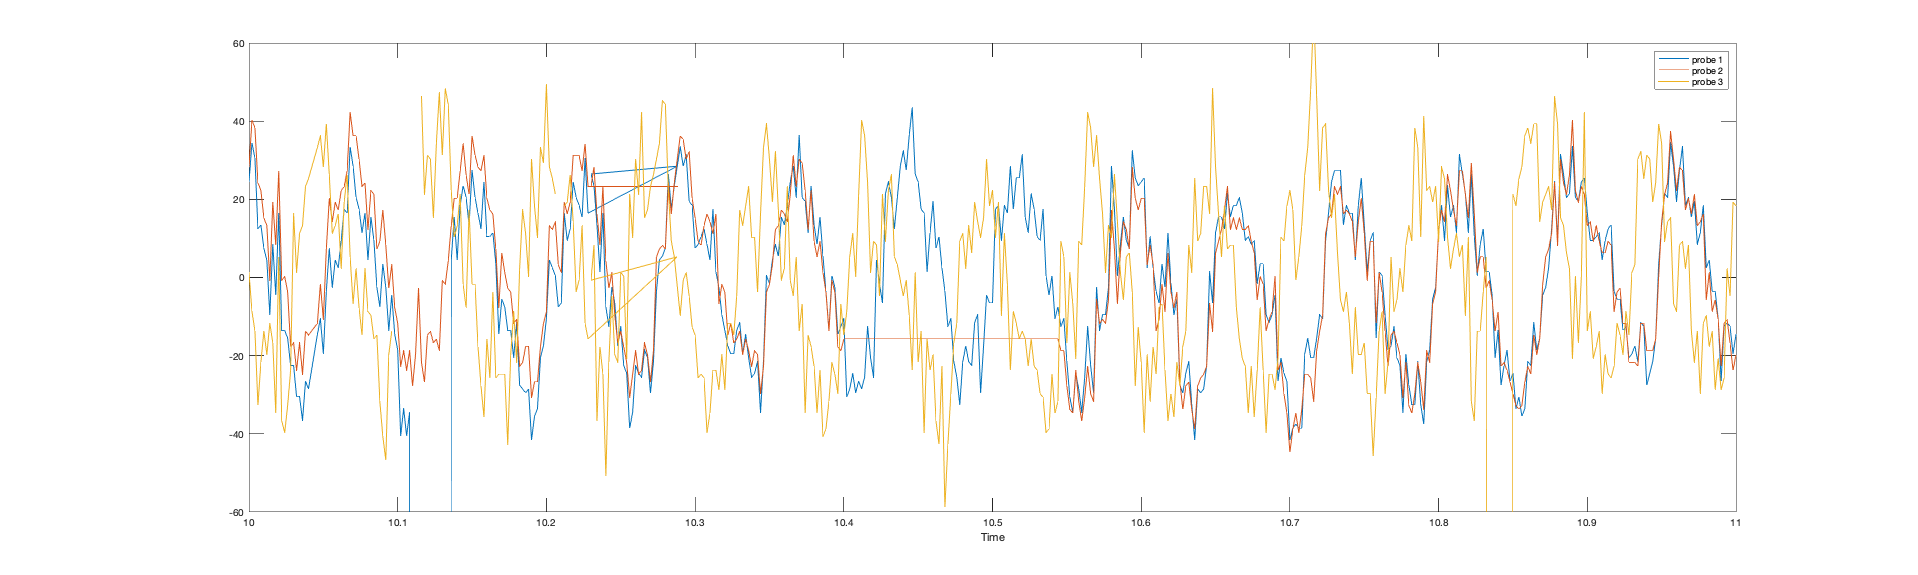

set(gcf, 'Position',  [100, 100, 2000, 600]); % setting the size of the plots
plot(data.Time,[data.probe1,data.probe2,data.probe3]);
ylim([-60 60]);
xlabel('Time')
legend('probe 1', 'probe 2', 'probe 3'); 

The MHKiT-Matlab QC module utilizes structures. WE need to convert the table of data into a structure. 

datast.time=data.Time;
datast.values = table2array(data(:,2:4));
datast

datast = struct with fields:
      time: [500×1 double]
    values: [500×3 double]


## Quality control tests

The following quality control tests are used to identify timestamp issues, corrupt data, data outside expected range, and stagnant data.

Each quality control tests results in the following information in a results structure:

- Cleaned data that has *NaN* in place of data that did not pass the quality control test

- Boolean mask with True/False that indicates if each data point passed the quality control test

### Check timestamp

Quality control analysis generally starts by checking the timestamp index of the data.

The follow test checks to see if 1) the data contains duplicate timestamps, 2) timestamps are not monotonically increasing, and 3) timestamps occur at irregular intervals (an interval of 0.002s is expected for this data).

If duplicate timestamps are found, the resulting structure keeps the first occurrence. If timestamps are not monotonic, the timestamps in the resulting structure are reordered.

% define expected frequency of the data, in seconds
frequency = 0.002;  

% run the timestamp quality control test
results = check_timestamp(datast,frequency); 

The cleaned data and boolean mask are shown below. 

disp(results)

    values: [501×3 double]
      mask: [501×3 int64]
      time: [1×501 datetime]



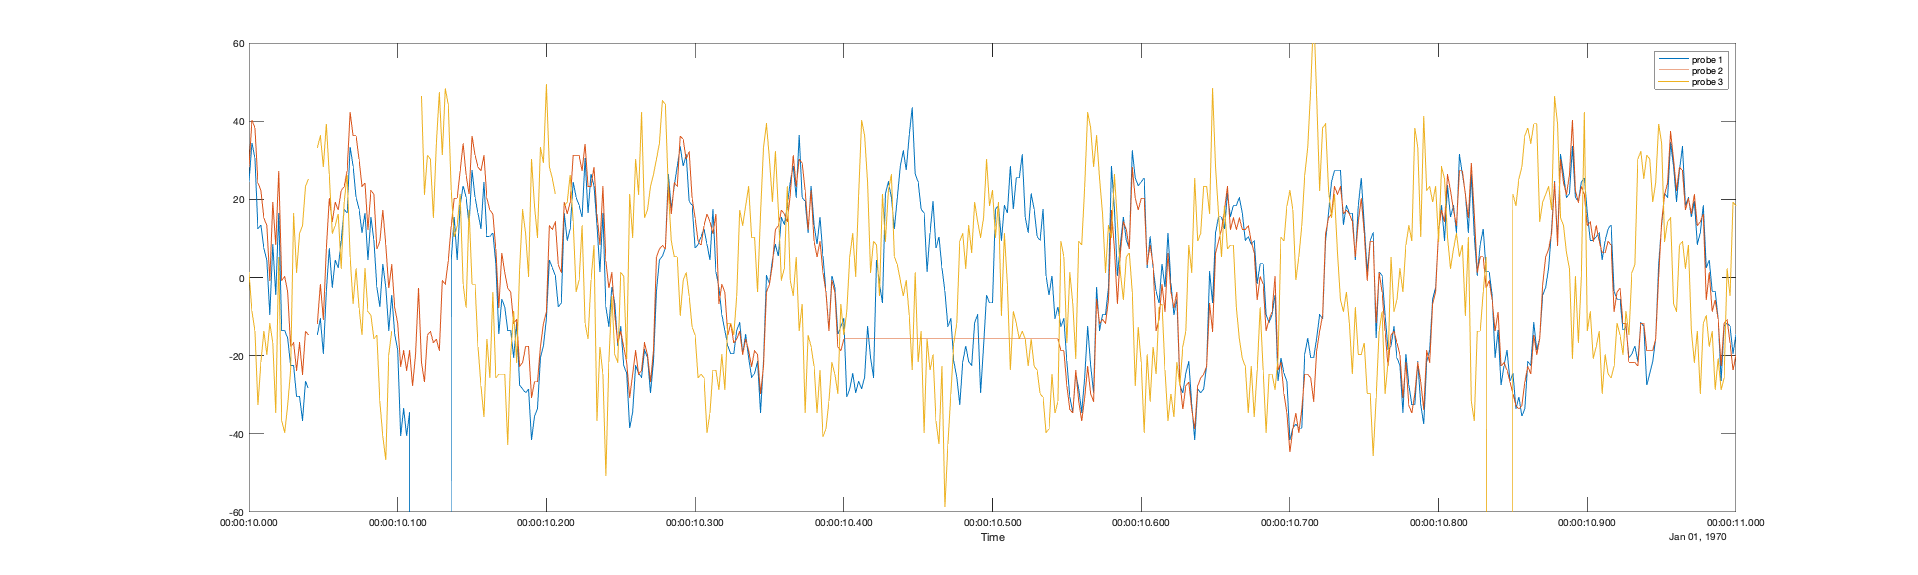

plot(results.time,results.values);
ylim([-60 60]);
xlabel('Time')
legend('probe 1', 'probe 2', 'probe 3');

### Check for corrupt data

In the following qualtiy control tests, the cleaned data from the previous test are used as input to the subsequent test. For each quality control test, a plot of the cleaned data is shown.

The quality control test below checks for corrupt data, indicated by a value of -999.

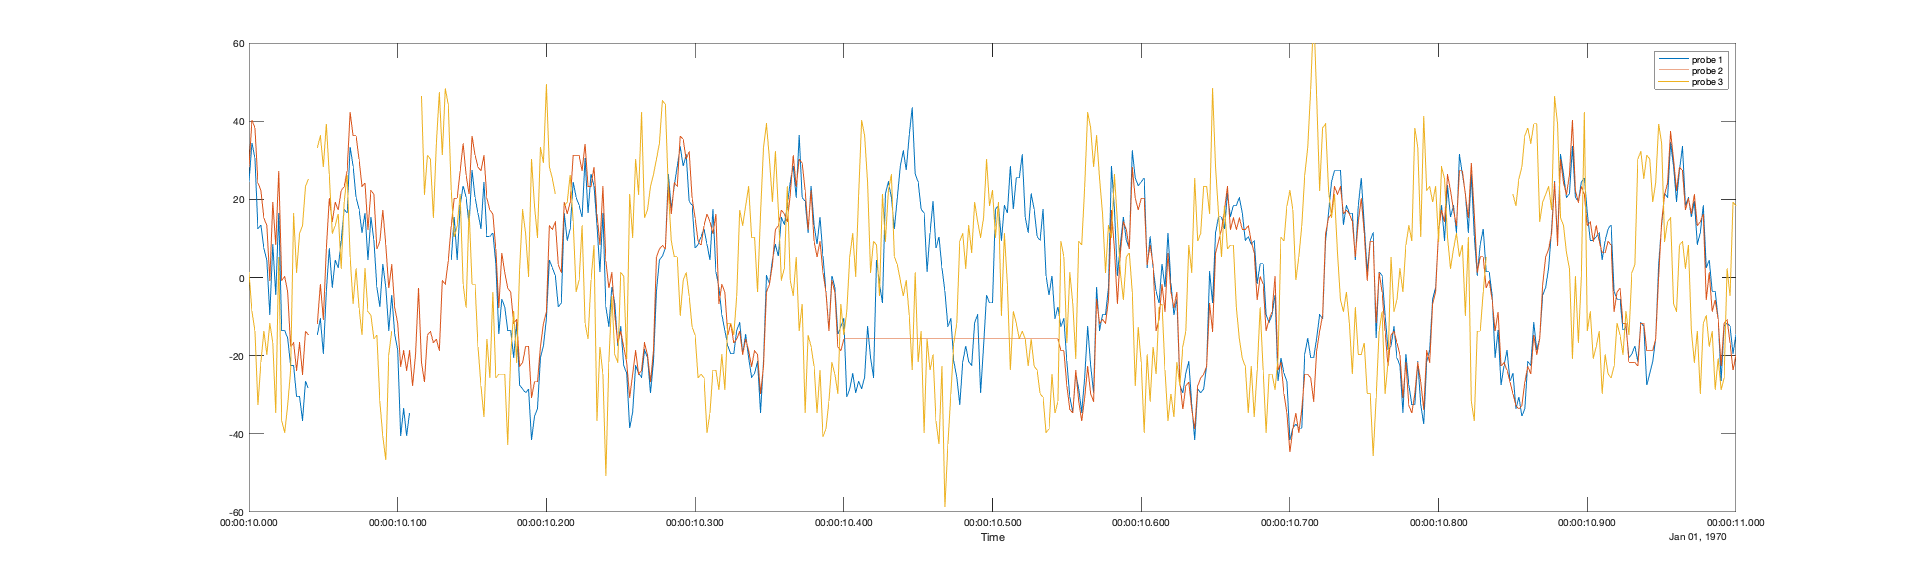

%define corrupt values
corrupt_values = {-999}; 

% run the corrupt data QC test
results = check_corrupt(results,corrupt_values); 

% Plot the cleaned data
plot(results.time,results.values);
ylim([-60 60]);
xlabel('Time')
legend('probe 1', 'probe 2', 'probe 3');

### Check for data ourside expected range

The next quality control test checks for data that is greater than 50 or less than -50.  Note that expected range tests can also be used to compare measured values to a model, or analyze the expected relationships between data columns.

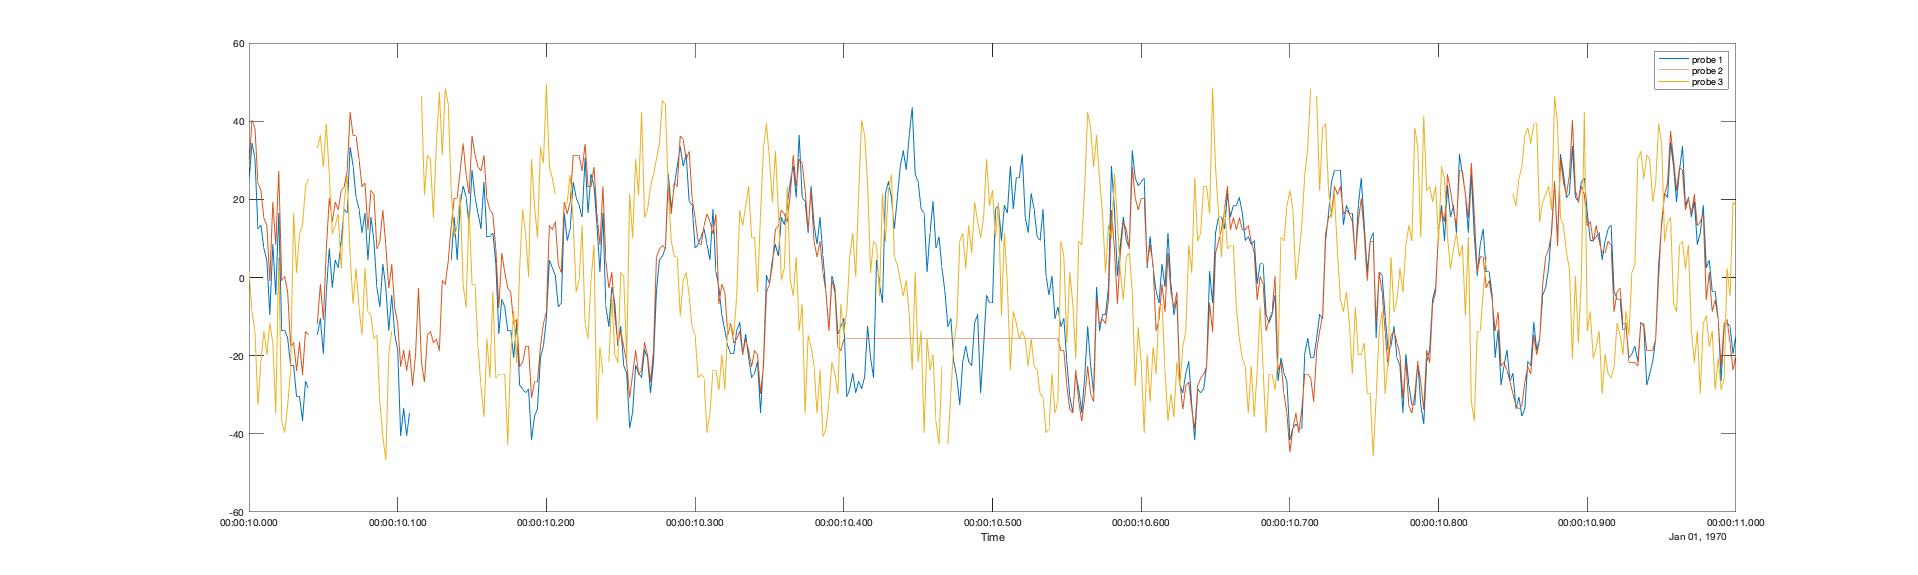

% define expected lower and upper bound
expected_bounds = [-50,50]; 

% run expected range QC test
results = check_range(results,expected_bounds); 

% Plot the cleaned data
plot(results.time,results.values);
ylim([-60 60]);
xlabel('Time')
legend('probe 1', 'probe 2', 'probe 3');

### Check for stagnant data

The final quality control test checks for stagnant data by looking for data that changes by less than 0.001 within a 0.02 second moving window.

% define the lower bound (no upper bound is specified in this example)
expected_bound = {0.001,py.None};  

% input the data, boundaries, py.None indicates apply to all columns, and window
results = check_delta(results,expected_bound); 

% plot cleaned data
plot(results.time,results.values);
ylim([-60 60]);
xlabel('Time')
legend('probe 1', 'probe 2', 'probe 3');

## Cleaned Data

The cleaned data can be used directly in MHKiT analysis, or the  missing values can be replaced using various methods before analysis is  run. Data replacement strategies are generally defined on a case by case basis. Pandas includes methods to interpolate, replace, and fill  missing values.

% Extract final cleaned data for MHKiT analysis
results

results = struct with fields:
    values: [501×3 double]
      mask: [501×3 int64]
      time: [1×501 datetime]


disp(results.values)

   24.4800   28.2700    1.3000
   34.4800   40.2700   -8.7000
   30.4800   38.2700  -13.7000
   12.4800   24.2700  -32.7000
   13.4800   22.2700  -21.7000
    7.4800   15.2700  -13.7000
    4.4800   13.2700  -19.7000
   -9.5200   -0.7300  -11.7000
    8.4800   19.2700  -16.7000
   -4.5200    8.2700  -34.7000
   16.4800   27.2700    5.3000
  -13.5200   -0.7300  -36.7000
  -13.5200    0.2700  -39.7000
  -15.5200   -3.7300  -32.7000
  -22.5300  -17.7300  -23.7000
  -22.5200  -16.7300   16.3000
  -30.5200  -23.7300    1.3000
  -30.5200  -16.7300   11.3000
  -36.5200  -24.7300   13.3000
  -26.5200  -13.7300   23.3000
  -28.5200  -14.7300   25.3000
       NaN       NaN       NaN
       NaN       NaN       NaN
  -14.5200  -11.7300   33.3000
  -10.5200   -1.7300   36.3000
  -19.5200  -10.7300   28.3000
   -3.5200    7.2700   39.3000
    7.4800   20.2700   26.3000
   -2.5200   14.2700   11.3000
    4.4800   19.2700   13.3000
    2.4800   17.2700   16.3000
    9.4800   22.2700    2.3000
   17.48